clear
clc
windowSize = 4096;
hopSize = 2048;
BPM = 120;
beats = 1/(BPM/60)

beats = 0.5000

quantification = beats/16 %double croche

quantification = 0.0313

wavFile = 'AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav'

wavFile = 'AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav'

[x,fs] = audioread(wavFile);
window = hann(windowSize,"symmetric")

window =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


x = x(:,1)

x =    -0.0002
   -0.0004
   -0.0005
   -0.0006
   -0.0007
   -0.0007
   -0.0008
   -0.0008
   -0.0009
   -0.0009


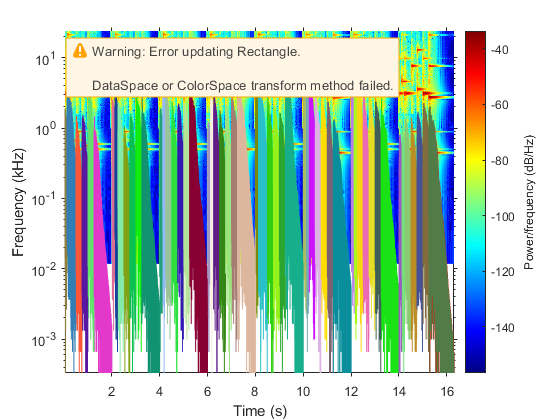

spectrogram(x,windowSize,windowSize-hopSize,windowSize,fs,'yaxis')
colormap jet
set(gca, 'YScale', 'log')


%first methode
audio = miraudio(wavFile,'Normal');

Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing mirsum related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Elapsed time is 0.280239 seconds.


Computing mirfilterbank related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
 
filterBank is the Audio waveform related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav, of sampling rate 48000 Hz.


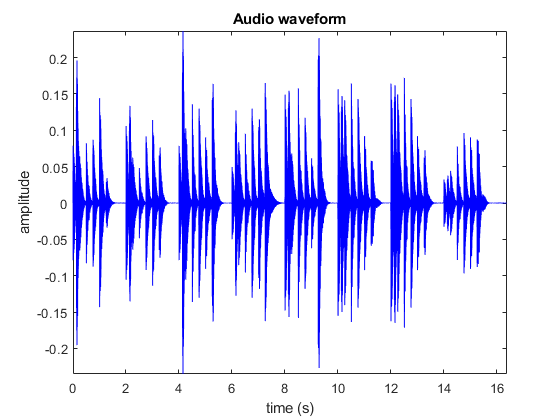

Its content is displayed in Figure 83.
 



filterBank = mirfilterbank(audio,'Gammatone','Channel',7)

Computing mirenvelope related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
 
enveloppe is the Differentiated envelope (half-wave rectified) related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav, of sampling rate 3000 Hz.


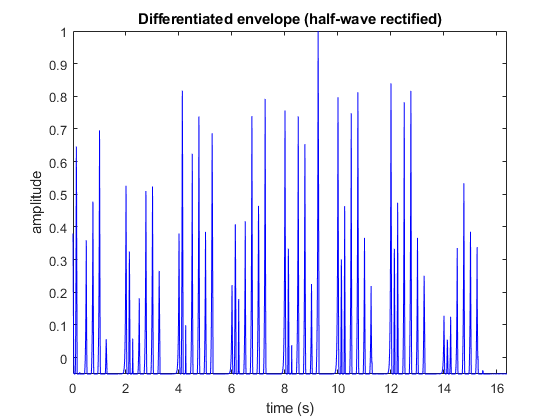

Its content is displayed in Figure 84.
 


%methode de suiveur envelope avec peak picking
enveloppe = mirenvelope(filterBank, 'FilterType', 'IIR','HalfwaveCenter','Diff','Normal','Center')

Computing mirpeaks related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
 
envelopepeaks is the Differentiated envelope (half-wave rectified) related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav, of sampling rate 3000 Hz.


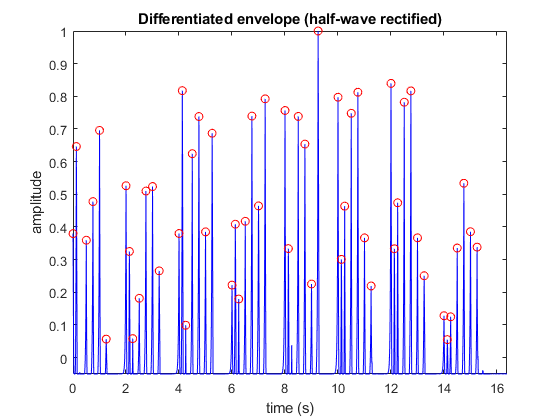

Its content is displayed in Figure 85.
 



envelopepeaks = mirpeaks(enveloppe,'Threshold',0.02,'Reso',quantification)

envelopedata =  mirgetdata(envelopepeaks)

envelopedata =     9.2511
   12.0018
    4.1259
   12.7524
   10.7524
   10.0018
    7.2518
   12.5018
    8.0018
   10.5018


envelopedataSort = sort(envelopedata(:,:,1))

envelopedataSort =     0.0018
    0.1260
    0.5018
    0.7524
    1.0018
    1.2531
    2.0018
    2.1272
    2.2536
    2.5018




nbrNotes = length(envelopedataSort)

nbrNotes = 54

 
sg is the Audio waveform related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav, of sampling rate 48000 Hz.


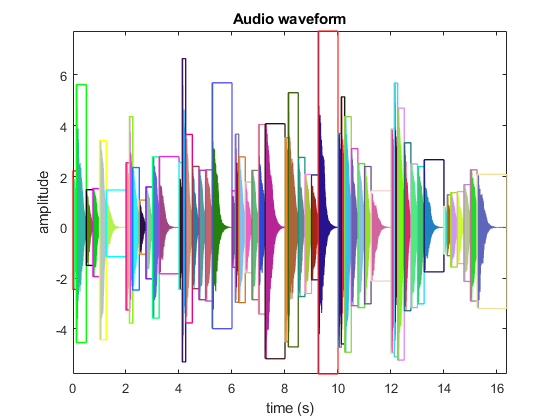

Its content is displayed in Figure 86.
 


sg = mirsegment(audio,envelopepeaks)

segmentPosition = get(sg,'FramePos')

segmentPosition = 1×1 cell array
    {1×55 cell}


posOfLastSg = segmentPosition{1}(size(segmentPosition{1},2))

posOfLastSg = 1×1 cell array
    {2×1 double}



%store the segmented data
for i =1:nbrNotes
    
    
    if i == nbrNotes
        segmentedNotes{i} = miraudio(audio,'Extract' , posOfLastSg{1}(1),posOfLastSg{1}(2));
        duration(i) = 0.25;
    else
        segmentedNotes{i} = miraudio(audio,'Extract' ,envelopedataSort(i),envelopedataSort(i+1));
        duration(i) = envelopedataSort(i+1)-envelopedataSort(i);
    end
    theAudio = mirgetdata(segmentedNotes{i});
    theAudio = theAudio.';
    [time, f0] = yin_estimator(theAudio,48000);
    
    stdF0 = median(f0);
    
    midifreq (i,1) = round( hz2midi(stdF0));
end

Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...
Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE

Computing miraudio related to AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav...




matrix(:,1) = envelopedataSort(:)/beats;
matrix(:,2) = duration/beats;
matrix(:,3) = 1.0;
matrix(:,4) = midifreq;
matrix(:,5) = 100;
matrix(:,6) = envelopedataSort(:);
matrix(:,7) = duration(:);


writemidi(matrix,'miditest.mid',BPM);